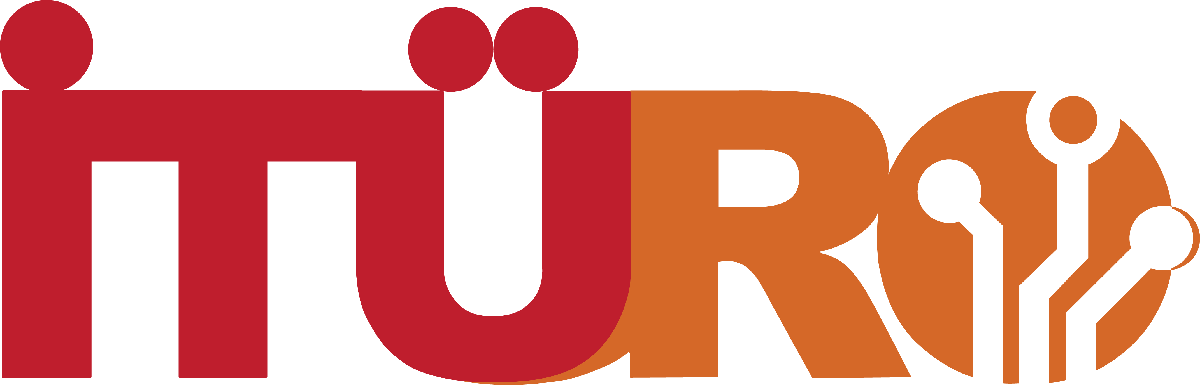

# **ALGOLAB 2023**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com*

## 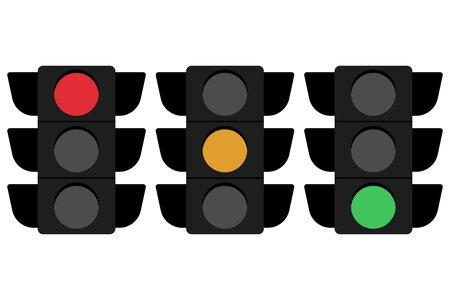

##  

## TRAFİK IŞIKLARI

Bir şehrin planlaması kapsamında, yeni hizmete sunulan bir dörtyol ağzına konacak trafik ışıklarının zamanlamasının ayarlanması gerekmektedir. Bu dörtyol ağzına aşağıda gösterildiği gibi 4 adet trafik ışığı yerleştirilecektir:

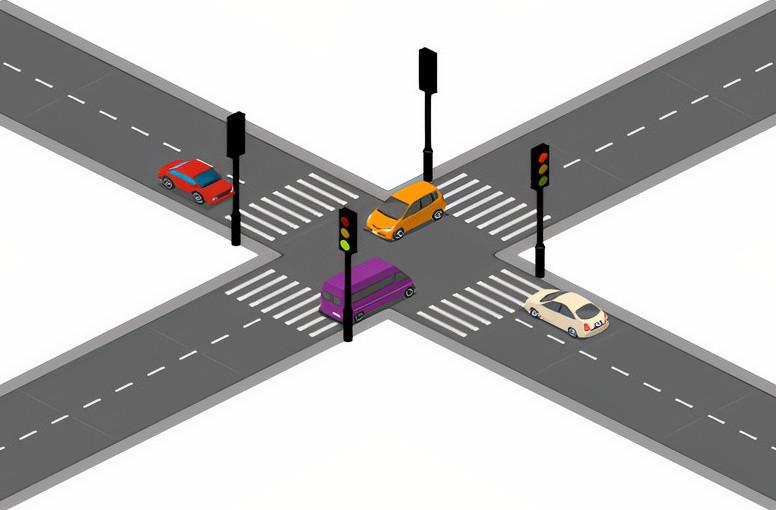

Trafiğin verimli bir biçimde işlemesi açısından ışıklar karşılıklı olarak aynı renkte olacaktır. Örneğin yukarıdaki senaryoda sol çaprazdaki trafik ışıkları kırmızı yanarken sağ çaprazdaki trafik ışıkları yeşil yanmaktadır. Bir süre sonra tüm ışıklar aynı anda sarı renge döner ve hemen sonrasında sol çaprazdaki ışıklar yeşil yanarken sağ çaprazdaki ışıklar kırmızı yanar. Bu iş için görevlendirilen mühendise aşağıdaki bilgiler verilmiştir:

- Trafik ışıkları $30$ saniye boyunca kırmızı yanar.

- Trafik ışıkları $1$ saniye boyunca sarı yanar.

- Trafik ışıkları $30$ saniye boyunca yeşil yanar.

- Sol çaprazdaki ışıklar kırmızı yanarken sağ çaprazdaki ışıklar yeşil yanar.

- Sol çaprazdaki ışıklar yeşil yanarken sağ çaprazdaki ışıklar kırmızı yanar.

- Tüm ışıklar aynı anda sarı yanar.

Bu problemin çözülmesi için mühendise ışıkların başlangıç renklerini içeren `L_init` matrisi verilmiştir. Bu matris

L_init = ['R', '-', 'G';
          '-', '-', '-';
          'G', '-', 'R'];

veya

L_init = ['G', '-', 'R';
          '-', '-', '-';
          'R', '-', 'G'];

olabilir. Burada `R` ve `G` sırasıyla kırmızı ve yeşil ışığı ifade etmektedir. Işıklar başlangıç renklerinde $30$ saniye yandıktan sonra sarıya dönerler ve bu durumda matris aşağıdaki gibi olur:

L = ['Y', '-', 'Y';
     '-', '-', '-';
     'Y', '-', 'Y'];

Işıklar sarı renkte 1 saniye yandıktan sonra da kırmızıysa yeşile, yeşilse de kırmızıya dönerler. Mühendisin görevi, bir `t` $> 0$ anında ışıkların rengini içeren `L` matrisini bulmaktır.

**FONKSİYON GİRDİLERİ**

- `L_init (3x3 char)`

- `t (1x1 double)`

**FONKSİYON ÇIKTILARI**

- `L (3x3 char)`

**ÖRNEK-1**

L_init = ['R', '-', 'G';
          '-', '-', '-';
          'G', '-', 'R'];
t = 25;
L = ['R', '-', 'G';
     '-', '-', '-';
     'G', '-', 'R'];

**ÖRNEK-2**

L_init = ['R', '-', 'G';
          '-', '-', '-';
          'G', '-', 'R'];
t = 31;
L = ['Y', '-', 'Y';
     '-', '-', '-';
     'Y', '-', 'Y'];

**ÖRNEK-3**

L_init = ['G', '-', 'R';
          '-', '-', '-';
          'R', '-', 'G'];
t = 60;
L = ['R', '-', 'G';
     '-', '-', '-';
     'G', '-', 'R'];